Import SS and Convert to DT

clear;

%system dynamics

m_pend = 0.312;     %kg
m_cart = 0.493;     %kg
I_pend = 0.00024;   %kg*m^2
l = 0.04;           %from rotation point to COM
g = 9.8;            %m/s^2
f = 0.01;           %frictional coefficient --make this higher???
K_T = 0.11;         %N*m/A
R_motor = 10;       %ohm
r_wheel = 0.0335;   %m

% SS matrices

A21 = -(I_pend+m_pend*l^2)*f / (I_pend*(m_cart + m_pend)+m_cart*m_pend*l^2);
A22 = (m_pend^2*g*l^2) / (I_pend*(m_cart+m_pend)+m_cart*m_pend*l^2);
A41 = (-m_pend*l*f) / (I_pend*(m_cart+m_pend)+m_cart*m_pend*l^2);
A42 = (m_pend*g*l*(m_cart+m_pend)) / (I_pend*(m_cart+m_pend)+m_cart*m_pend*l^2);

A = [ 0 1 0 0;
    0 A21 A22 0;
    0 0 0 1;
    0 A41 A42 0];

B2 = (I_pend+m_pend*l^2)/(I_pend*(m_cart+m_pend)+m_cart*m_pend*l^2);
B4 = (m_pend*l) / (I_pend*(m_cart+m_pend)+(m_cart*m_pend*l^2));

B = [0;
    B2;
    0
    B4];

C = [1 0 0 0;
    0 0 1 0];

D = [0;
    0];

%create SS and TF model

ts = 0.005; %s

sys_cont = ss(A,B,C,D);
sys_disc = c2d(sys_cont,ts);

%[num,denom] = ss2tf(A,B,C,D); %implicit ZoH
%sys_tf = [num, denom];

A = sys_disc.A; B = sys_disc.B; C = sys_disc.C; D = sys_disc.D;

Define LQR Parameters and Solve for Gains -- Baseline Controller

%Qlqr = diag([1,1,20,10]);
Qlqr = diag([1,5,50,1]);
Rlqr = 1;
[K_dlqr, Slqr, e] = dlqr(A, B, Qlqr, Rlqr);

K_v = K_dlqr * (1/(2*K_T/R_motor/r_wheel));
printOut = ['{ ', K_v(1), ', ', K_v(1), ', ', K_v(1), ', ', K_v(1), ' };'];
K_v = round(K_v, 3);
printOut = sprintf('K_dlqr = { %g, %g, %g, %g };',K_v(1), K_v(2), K_v(3), K_v(4));
disp(printOut)

K_dlqr = { -1.359, -3.848, 31.699, 2.491 };


%calculate motor saturation region based on 12V max
u_max = 2*K_T/R_motor/r_wheel * 7;
u_min = -2*K_T/R_motor/r_wheel * 7;

Simulate with LQR as baseline

Xlqr = [0 ;0 ;pi/6 ;0];
Ulqr = 0;
T = 3000;
time_step = 0.005;
time = 1:time_step:T*time_step+1;
freqLqr = 1/5;
sq_wav_lqr = (pi/12)*square(2*pi*freqLqr*time,50);
lqr_ref = [zeros(1,length(sq_wav_lqr)); zeros(1,length(sq_wav_lqr)); zeros(1,length(sq_wav_lqr)); zeros(1,length(sq_wav_lqr))];
tic
for i = 1:T-1
    XlqrAct(i,:) = Xlqr;
    err = Xlqr - lqr_ref(:,i);
    u_curr = -K_dlqr*err;
    u_curr = min(u_max,max(u_min, u_curr));  %add motor saturation!
    Xlqr = A*Xlqr + B*u_curr;
    %add impulses at certain steps - modeled only as angular velocity
    %component
    if i == 1500 %mod(i,400) == 0
        Xlqr = Xlqr + [0;0;0;-8];
    end
    Ulqr(i) = u_curr;
end
toc

Elapsed time is 0.020752 seconds.


XlqrAct(i+1,:) = Xlqr;

Plot LQR All States

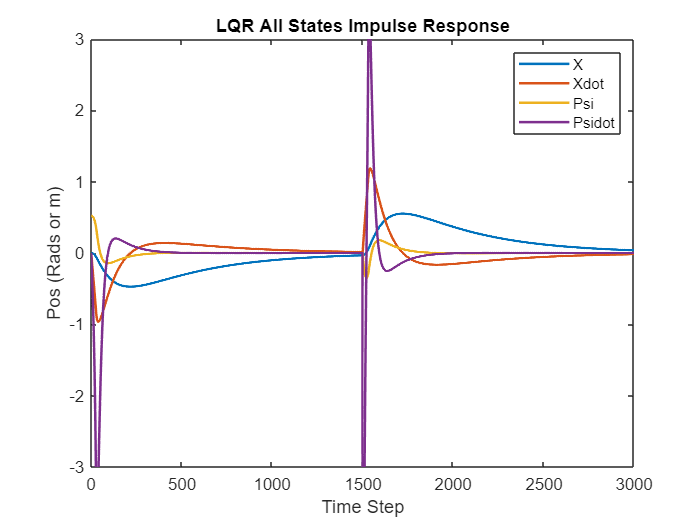

figure(4)
plot([1:T],XlqrAct(:,1), [1:T],XlqrAct(:,2),[1:T],XlqrAct(:,3), [1:T],XlqrAct(:,4), 'LineWidth',1.5);
ylim([-3,3]);
xlabel("Time Step");
ylabel("Pos (Rads or m)");
title("LQR All States Impulse Response")
legend("X", "Xdot", "Psi", "Psidot")

Plot LQR Baseline Case

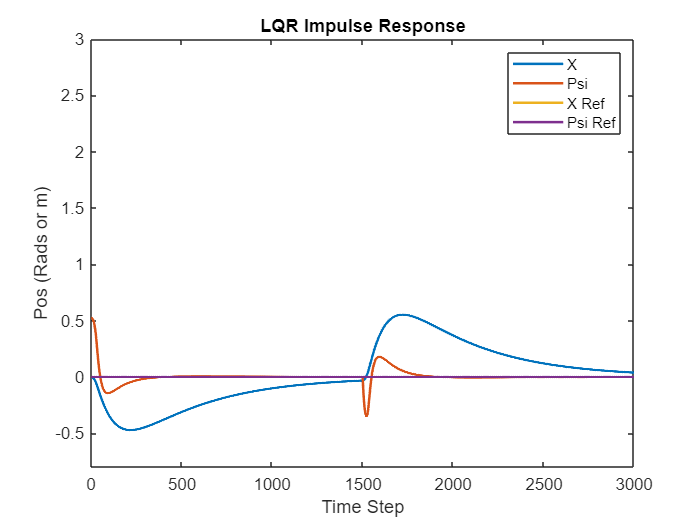

figure(1)
plot([1:T],XlqrAct(:,1), [1:T],XlqrAct(:,3),[1:T],lqr_ref(1,1:T), [1:T],lqr_ref(3,1:T), 'LineWidth',1.5);
ylim([-.8,3]);
xlabel("Time Step");
ylabel("Pos (Rads or m)");
title("LQR Impulse Response")
legend("X", "Psi", "X Ref", "Psi Ref")

Plot LQR Input Force

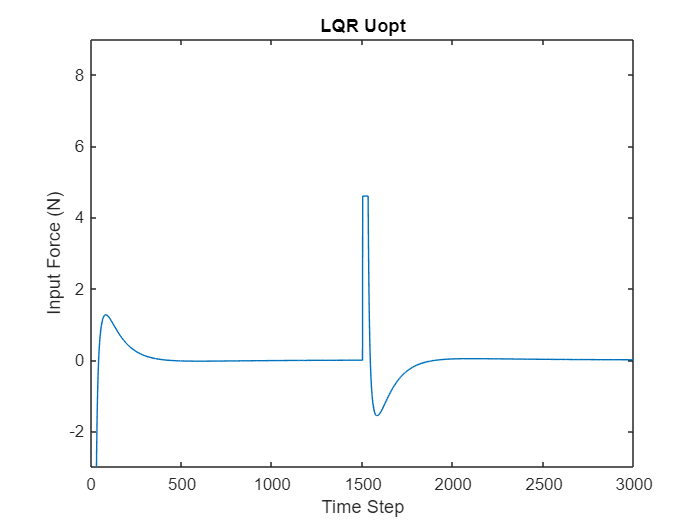

figure(2)
plot(Ulqr)
ylim([-3,9]);
xlabel("Time Step");
ylabel("Input Force (N)");
title("LQR Uopt")

Plot LQR Motor Voltage

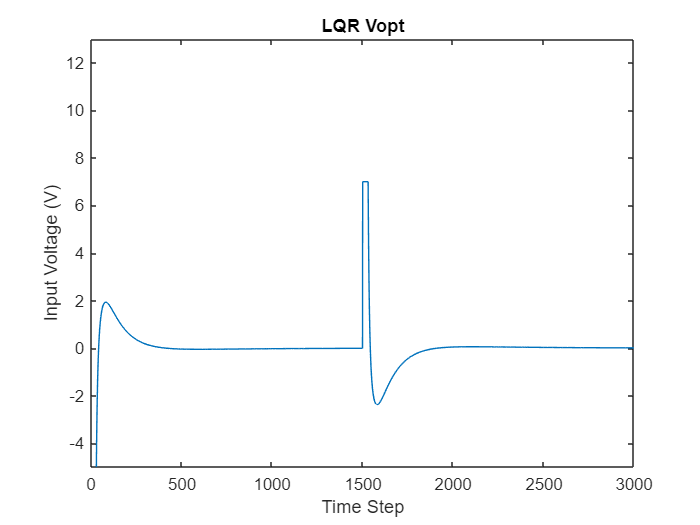

voltage_motors = Ulqr * (R_motor * r_wheel / 2 / K_T);
figure(3)
plot(voltage_motors)
ylim([-5,13]);
xlabel("Time Step");
ylabel("Input Voltage (V)");
title("LQR Vopt")